clear all; clc;

load Sa1.mat;

I = 48;
Fs = 16000;
FsI = Fs*I;

%design 3 stage interpolator
d = fdesign.interpolator(I,'lowpass','Fp,Fst,Ap,Ast',5000,6200,0.08,58,FsI)

d =   interpolator with properties:

          MultirateType: 'Interpolator'
               Response: 'Lowpass'
    InterpolationFactor: 48
          Specification: 'Fp,Fst,Ap,Ast'
            Description: {4×1 cell}
    NormalizedFrequency: 0
                     Fs: 768000
                  Fs_in: 16000
                 Fs_out: 768000
                  Fpass: 5000
                  Fstop: 6200
                  Apass: 0.0800
                  Astop: 58


filt3stage = design(d,'multistage','Nstages',3,'SystemObject',true)

filt3stage =   dsp.FilterCascade with properties:

         Stage1: [1×1 dsp.FIRInterpolator]
         Stage2: [1×1 dsp.FIRInterpolator]
         Stage3: [1×1 dsp.FIRInterpolator]
    CloneStages: true


%pass signal through interpolator
wavedata_48I = filt3stage(wavedata);

%analyse interpolator signal
% plot(wavedata_48I)
% plotfft(wavedata_48I,1/FsI,[-FsI/2000 FsI/2000]);

%create sputious frequencies created in transmission
t = 0:1/FsI:8-1/FsI;
spur = .004*sin(16e3*2*pi*t)+.004*sin(50e3*2*pi*t)+.004*sin(100e3*2*pi*t)+.004*sin(150e3*2*pi*t);
%add to interpolator data
wavedata_spur = wavedata_48I + spur'

wavedata_spur =          0
    0.0088
    0.0105
    0.0058
    0.0015
    0.0022
    0.0050
    0.0051
    0.0024
    0.0012


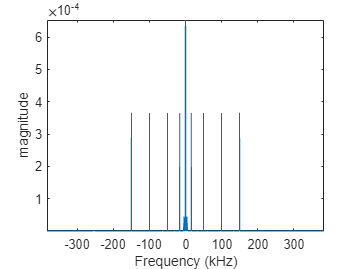

plotfft(wavedata_spur,1/FsI,[-FsI/2000 FsI/2000]);

%design 3-stage decimator
D = I/2

D = 24

FsD = FsI/2;
d2 = fdesign.decimator(D,'lowpass','Fp,Fst,Ap,Ast',5000,6200,0.08,58,FsD)

d2 =   decimator with properties:

          MultirateType: 'Decimator'
               Response: 'Lowpass'
       DecimationFactor: 24
          Specification: 'Fp,Fst,Ap,Ast'
            Description: {4×1 cell}
    NormalizedFrequency: 0
                     Fs: 384000
                  Fs_in: 384000
                 Fs_out: 16000
                  Fpass: 5000
                  Fstop: 6200
                  Apass: 0.0800
                  Astop: 58


filt2 = design(d2,'multistage','Nstages',3,'SystemObject',true)

filt2 =   dsp.FilterCascade with properties:

         Stage1: [1×1 dsp.FIRDecimator]
         Stage2: [1×1 dsp.FIRDecimator]
         Stage3: [1×1 dsp.FIRDecimator]
    CloneStages: true


%pass interpolated signal through decimator
wavedata_D = filt2(wavedata_spur);

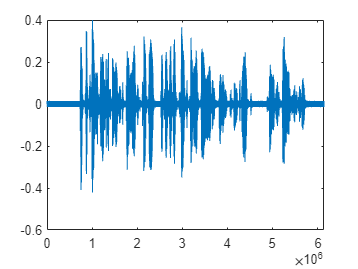

%plot decimator signal
plot(wavedata_spur)

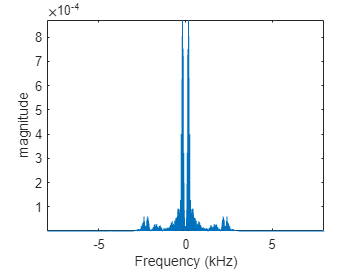

plot(wavedata_D)
plotfft(wavedata_D,1/Fs,[-16 16]);

%cost of decimator
filt2.order

ans = 1022

length(filt2)

ans = 1

filt2.cost

ans = struct with fields:
                  NumCoefficients: 111
                        NumStates: 105
    MultiplicationsPerInputSample: 8.4167
          AdditionsPerInputSample: 8.0417


%plot decimator
fvtool(filt2);